% % getting whole group workflow (up til now) together

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();

nGroup = 3

% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'


% group matrix

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% LOCO NO PUP - makes group matricies, need this for all other figs/analyses

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% 2 sample t test on trial vectors (C=0 vs all other C's, one state at a time)

% need output from HISTO code to run stats tests in cell below

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7
visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control
sess = 1:nGroup

sess =      1     2     3



state = 'loRun'

state = loRun

[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiRun'

state = hiRun

[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% picking an alpha value (correct for mult. comparisons)
n_cons = 7 % # contrasts 

n_cons = 7

denom = n_cons-1 % # comparisons

denom = 6

alf = 0.05/denom % bonferroni correction for multiple comparisons

alf = 0.0083

% 2 sample t test, c=0 vs all other cons

% NOTE: run this code once for each beh state, change var name at end each time

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup

sess =      1     2     3


%sess = 1

% this code is similar to the histo code in that it gathers all trials across all sess for each con,
% but different in that
% it then performs a 2 sample t test and saves out the test statistics
% also the histo function saves all the trials as nested cell array, which I don't need here

clear h_p_cil_cih__tstats_AllPairs
clear tstats_AllPairs

clear h_p_cil_cih__tstats_AllPairs_AllPts
clear tstats_AllPairs_AllPts

clear h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs
clear tstats_AllPairs_AllPts_AllDurs

for d = durat
    
    for i = visArea
        
        clear c
        for c = 1 % zero contrast - collecting dist of df responses each trial for both states at zero contrast
        %for c = 1
        %for c = 1:length(uniqueContrasts)
            
            % get df for each trial vector across all sessions, c = 0
            clear zeroCon_lo_dthithCthNth_pkDfEachTrial
            zeroCon_lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear zeroCon_hi_dthithCthNth_pkDfEachTrial
            zeroCon_hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                zeroCon_lo_dthithCthNth_pkDfEachTrial = [zeroCon_lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                zeroCon_hi_dthithCthNth_pkDfEachTrial = [zeroCon_hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
            end % end n loop - now have all mean peak df values for each trial (c=0), all sessions pooled
            
        end % end c = 0 loop

        % next steps: collect dist of responses for each con besides zero, for each state (well, manually one at a time), 
        % and do stats comparison
        
        % for each contrast * except c = 0 (cuz will get N/A)
        clear c
        for c = cont(2:end)
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
            
                % get values for 1st sesson, cth dth ith trials
                 lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                 hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
           
            end % end n loop
            
            % PICK: LO or HI (C=0 vs CTH CON)
            
            %[h,p,ci,t_stats] = ttest2(zeroCon_lo_dthithCthNth_pkDfEachTrial,lo_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            %[h,p,ci,t_stats] = ttest2(zeroCon_hi_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            h_p_cil_cih__tstats_AllPairs(1,c-1) = h; % c-1 so index doesn't start at 2
            h_p_cil_cih__tstats_AllPairs(2,c-1) = p;
            h_p_cil_cih__tstats_AllPairs(3,c-1) = ci(1,1);
            h_p_cil_cih__tstats_AllPairs(4,c-1) = ci(1,2);
            tstats_AllPairs{1,c-1} = t_stats;

        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih__tstats_AllPairs_AllPts(:,:,i) = h_p_cil_cih__tstats_AllPairs;
        tstats_AllPairs_AllPts{i,:} = tstats_AllPairs;
        
    end % end i loop
    
    h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih__tstats_AllPairs_AllPts;
    tstats_AllPairs_AllPts_AllDurs{d,:} = tstats_AllPairs_AllPts;
   
    
end % end d loop

% stats param x comparison contrast x points
size(h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)

ans =      4     6     5


size(tstats_AllPairs_AllPts_AllDurs)

ans =      1     1



%loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs = h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs;
%size(loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)
%hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs = h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs;
%size(hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)

ans =      4     6     5


% for plotting, get CRF
% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 
% LO BEH STATE
% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts)

size_loRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts)

size_loRun_stdErrCRF_acrossSess_allPts =      5     7


% HI BEH STATE
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts)

size_hiRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts)

size_hiRun_stdErrCRF_acrossSess_allPts =      5     7


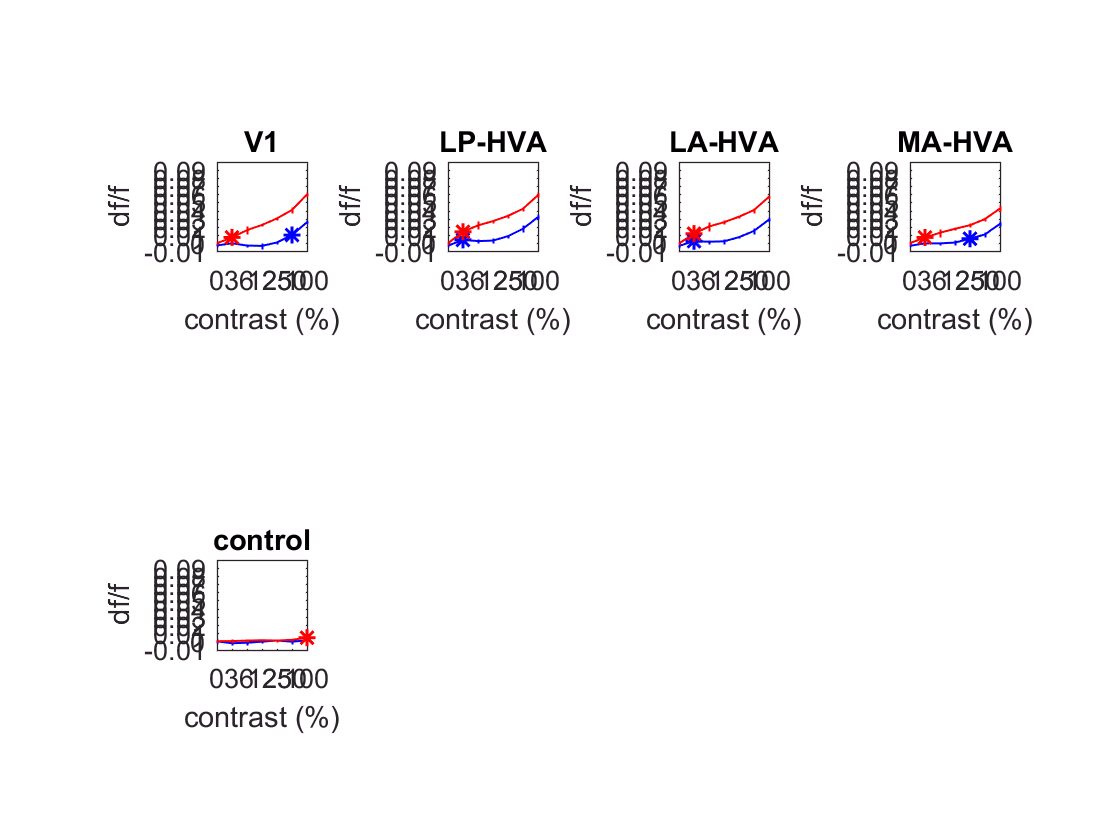

% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT CRFs w/asterisks

figure

% for each duration
clear d
for d = durat
    
    % for each point
    clear i
    for i = visArea
        
        % Plot the CRF for LO beh state
        
        % make a sub plot
        subplot(2,4,i)
        
        % plot LO beh state CRF
        x_axis = 1:length(uniqueContrasts);
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_loBehState(i,:),'b')
        errorbar(x_axis,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'-b','LineWidth',0.75) 
        hold on
        % plot HI beh state CRF
        %plot(x_axis,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,:),'r')
        errorbar(x_axis,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r','LineWidth',0.75)
        
        hold on
        
        % legend(stateLegend)
        
        % reset asterisk counter for each vis area/beh state:
        counter = 0; % once counter = 1, stop plotting asterisk
         
        % for LO beh state
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if loBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    plot(com+1,loRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'b*','LineWidth',1.1)
                    
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);
                    
                    %H=sigstar({{xt{1},xt{min(find(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    %set(H,'color','b')
                    
                    counter = counter + 1;
                
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop
        
        hold on
        
        % HI
        % set counter to zero for each state
        counter = 0;
        
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)
            
            if counter == 0
            
                if hiBehState_h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                    hold on
                    
                    plot(com+1,hiRun_mnCRF_acrossSess_AllDurAllPts(i,com+1),'r*','LineWidth',1.1)
                    clear xt
                    xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
                    set(gca,'xtick',1:7); 
                    set(gca,'xticklabel',xt);

                    %H=sigstar({{xt{1},xt{min(find(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,:,i) == 1))+1}}});
                    %set(H,'color','r')
                    
                    %ylim(yLimit)
        
                    counter = counter + 1;
                    
                end % end plot if statement
               
            end % end counter if statement
            
        end % end com loop
            
        title(reigons{i})
    
        ylim(yLimit) 
        xlim(xLimit)
    
        ylabel('df/f')
        xlabel('contrast (%)')
        
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %xt={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
    
        yt = [-0.01 0 0.01 0.02 0.03 0.04 0.05 0.06 0.07 0.08 0.09];
        %yt = [-0.01 0 0.02 0.04 0.06 0.08];
        set(gca,'YTick',yt)
        
        axis square
        
    end % end i loop 
    
end % end d loop

% same as above, but for KS test...
% c=0 vs all other cons

% NOTE: run this code once for each beh state, change var name at end each time

%durat = 1:length(uniqueDurations);
durat = 1

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup

sess =      1     2     3


%sess = 1

% this code is similar to the histo code in that it gathers all trials across all sess for each con,
% but different in that
% it then performs a 2 sample t test and saves out the test statistics
% also the histo function saves all the trials as nested cell array, which I don't need here

clear h_kstat_AllPairs
clear p_kstat_AllPairs
clear ks_stats_AllPairs

clear h_kstat_AllPairs_AllPts
clear p_kstat_AllPairs_AllPts
clear ks_stats_AllPairs_AllPts

clear h_kstat_AllPairs_AllPts_AllDurs
clear p_kstat_AllPairs_AllPts_AllDurs
clear ks_stats_AllPairs_AllPts_AllDurs

for d = durat
    
    for i = visArea
        
        clear c
        for c = 1 % zero contrast - collecting dist of df responses each trial for both states at zero contrast
        %for c = 1
        %for c = 1:length(uniqueContrasts)
            
            % get df for each trial vector across all sessions, c = 0
            clear zeroCon_lo_dthithCthNth_pkDfEachTrial
            zeroCon_lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear zeroCon_hi_dthithCthNth_pkDfEachTrial
            zeroCon_hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                zeroCon_lo_dthithCthNth_pkDfEachTrial = [zeroCon_lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                zeroCon_hi_dthithCthNth_pkDfEachTrial = [zeroCon_hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
            end % end n loop - now have all mean peak df values for each trial (c=0), all sessions pooled
            
        end % end c = 0 loop

        % next steps: collect dist of responses for each con besides zero, for each state (well, manually one at a time), 
        % and do stats comparison
        
        % for each comparison between cth con & zeroth con
        clear com
        for com = cont(2:end)
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
            
                % get values for 1st sesson, cth dth ith trials
                 lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,com}];
                 hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,com}];
           
            end % end n loop
            
            % PICK: LO or HI (C=0 vs CTH CON)
            
            %[h,p,ci,t_stats] = ttest2(zeroCon_lo_dthithCthNth_pkDfEachTrial,lo_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            %[h,p,ci,t_stats] = ttest2(zeroCon_hi_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            %[h,p,ks_stats] = kstest2(zeroCon_lo_dthithCthNth_pkDfEachTrial,lo_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            [h,p,ks_stats] = kstest2(zeroCon_hi_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            h_kstat_AllPairs(1,com-1) = h; % c-1 so index doesn't start at 2
            p_kstat_AllPairs(1,com-1) = p';
            
            ks_stats_AllPairs{1,com-1} = ks_stats;

        end % end comparisons loop
        
        % collect stats x contrast grid for each point
        %h_p_cil_cih__tstats_AllPairs_AllPts(:,:,i) = h_p_cil_cih__tstats_AllPairs;

        h_kstat_AllPairs_AllPts(:,:,i) = h_kstat_AllPairs;
        p_kstat_AllPairs_AllPts(:,:,i) = p_kstat_AllPairs;

        ks_stats_AllPairs_AllPts{i,:} = tstats_AllPairs;
        
    end % end i loop
    
    %h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih__tstats_AllPairs_AllPts;
    
    h_kstat_AllPairs_AllPts_AllDurs(:,:,:,d) = h_kstat_AllPairs_AllPts;
    p_kstat_AllPairs_AllPts_AllDurs(:,:,:,d) = p_kstat_AllPairs_AllPts;
    
    ks_stats_AllPairs_AllPts_AllDurs{d,:} = tstats_AllPairs_AllPts;
   
    
end % end d loop

% stats param x comparison contrast x points
size(h_kstat_AllPairs_AllPts_AllDurs)

ans =      1     6     5


size(p_kstat_AllPairs_AllPts_AllDurs)

ans =      1     6     5


size(ks_stats_AllPairs_AllPts_AllDurs)

ans =      1     1



% loBehState_h_kstat_AllPairs_AllPts_AllDurs = h_kstat_AllPairs_AllPts_AllDurs;
% loBehState_p_kstat_AllPairs_AllPts_AllDurs = p_kstat_AllPairs_AllPts_AllDurs;
% loBehState_ks_stats_AllPairs_AllPts_AllDurs = ks_stats_AllPairs_AllPts_AllDurs;

hiBehState_h_kstat_AllPairs_AllPts_AllDurs = h_kstat_AllPairs_AllPts_AllDurs;
hiBehState_p_kstat_AllPairs_AllPts_AllDurs = p_kstat_AllPairs_AllPts_AllDurs;
hiBehState_ks_stats_AllPairs_AllPts_AllDurs = ks_stats_AllPairs_AllPts_AllDurs;

% interpoalate contrsntrast as funciton of respnse, fnd x value for y = 50% max
% interp1d(response, contrast, 1/2 max reponse) 